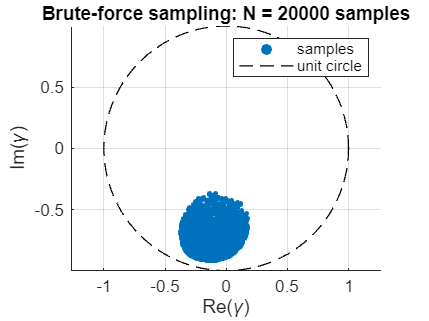

run("data/c3x7_s1602_l48.m")

% Regularize diagonals if very small (avoid divide-by-zero)
eps_reg = 1e-12;
T11 = (T11 + T11')/2;
T22 = (T22 + T22')/2;
T11 = T11 + eps_reg*trace(T11)/3 * eye(3);
T22 = T22 + eps_reg*trace(T22)/3 * eye(3);

% Precompute for speed if needed
% We'll compute gamma(w) directly for many w vectors:
N = 20000; % number of random polarization samples (adjust)
gamma_vals = complex(zeros(N,1));
%3xN matrix
w_store = complex(zeros(3,N));

% sample w uniformly on complex unit sphere
%We dont need to check for repeated samples, because we are sampling from a
%continious distribution. So statistaclly we should not get identical
%samples.
for k = 1:N
    % randn(3,1) creates three random normally distrubited numbers, so that
    % we are uniform on the complex sphere.
    z = (randn(3,1) + 1i*randn(3,1));
    %Normalize
    w = z / norm(z);
    %Store the value
    w_store(:,k) = w;
    %Calculate numerator
    num = w' * O12 * w;
    %Calculate denomerator
    denom = sqrt((w' * T11 * w) * (w' * T22 * w));
    %calculate gamma and store it
    gamma_vals(k) = num / denom;
end

% --- Plot the brute-force sampled points ---
figure('Name','Brute-force coherence sampling','NumberTitle','off');
scatter(real(gamma_vals), imag(gamma_vals), 8, 'filled'); axis equal; grid on;
xlabel('Re(\gamma)'); ylabel('Im(\gamma)');
title(sprintf('Brute-force sampling: N = %d samples', N));
% draw unit circle for reference
hold on; th = linspace(0,2*pi,500); plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
legend('samples','unit circle');